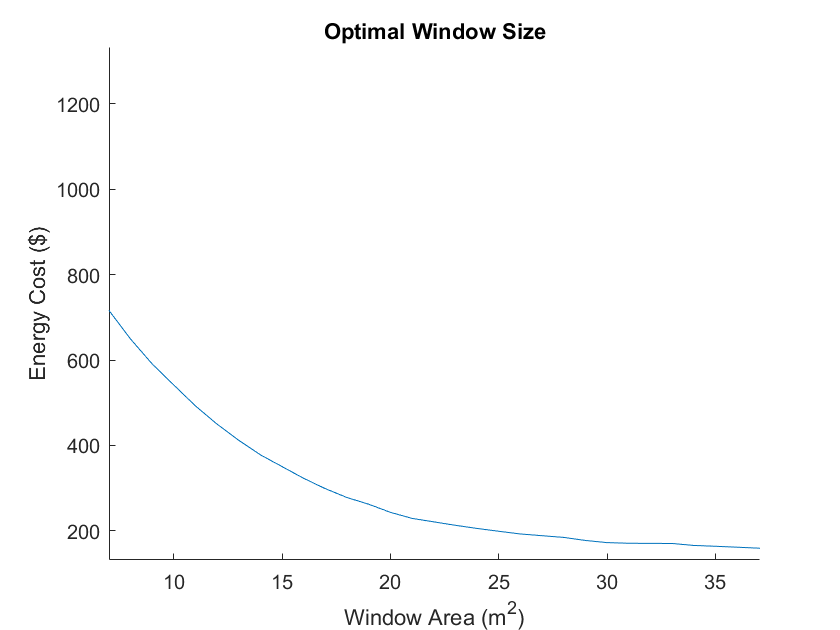

bill = NaN(40,1);
ave = NaN(40,1);

for i=1:41
    [cost, temp] = eulerTest(i-1);
    bill(i) = cost;
    ave(i) = mean(temp);
end

clf;
figure(1);
hold on;
plot([0:40],bill);
title('Optimal Window Size')
xlabel('Window Area (m^2)');
ylabel('Energy Cost ($)');

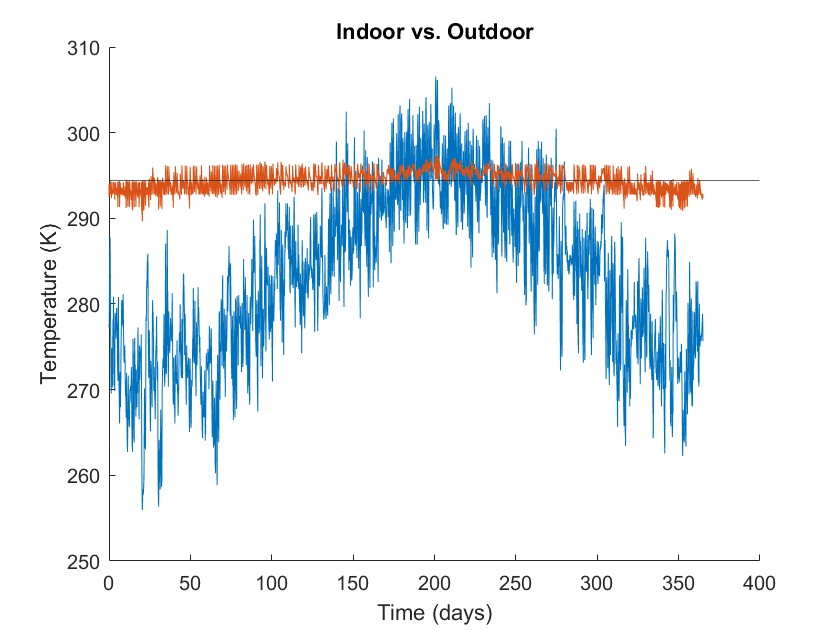

clf; hold on;
[cost,temp] = eulerTest(15);
plot(T,airTemperatureK);
plot(T,temp);
title('Indoor vs. Outdoor')
xlabel('Time (days)');
ylabel('Temperature (K)');
yline(mean(temp));